% Filenames
filenames1 = {'02-26-2016_21_07_08'
'02-26-2016_21_06_18'
'02-26-2016_21_05_27'
'02-26-2016_21_04_36'
'02-26-2016_21_03_46'
'02-26-2016_21_02_55'
'02-26-2016_21_02_04'
'02-26-2016_21_01_14'
'02-26-2016_21_00_23'
'02-26-2016_20_59_32'
'02-26-2016_20_58_42'
'02-26-2016_20_57_00'}; % 122 266 70 70 15

filenames2 = {'02-26-2016_22_48_40'
'02-26-2016_22_47_52'
'02-26-2016_22_47_03'
'02-26-2016_22_46_14'
'02-26-2016_22_45_25'
'02-26-2016_22_44_36'
'02-26-2016_22_43_47'
'02-26-2016_22_42_58'
'02-26-2016_22_42_10'
'02-26-2016_22_41_21'
'02-26-2016_22_40_32'
'02-26-2016_22_39_43'
'02-26-2016_22_38_54'
'02-26-2016_22_35_39'
'02-26-2016_22_34_50'}; % 120 276

filenames3={'02-26-2016_23_38_58'
'02-26-2016_23_38_07'
'02-26-2016_23_37_16'
'02-26-2016_23_36_25'
'02-26-2016_23_35_35'
'02-26-2016_23_34_44'
'02-26-2016_23_33_53'
'02-26-2016_23_33_03'
'02-26-2016_23_32_12'
'02-26-2016_23_31_21'
'02-26-2016_23_30_31'
'02-26-2016_23_29_40'
'02-26-2016_23_28_50'
'02-26-2016_23_27_59'
'02-26-2016_23_27_08'
'02-26-2016_23_26_18'
'02-26-2016_23_25_27'
'02-26-2016_23_23_22'
'02-26-2016_23_22_31'
'02-26-2016_23_21_41'
'02-26-2016_23_20_50'}; % 130 283

filenames = filenames2;


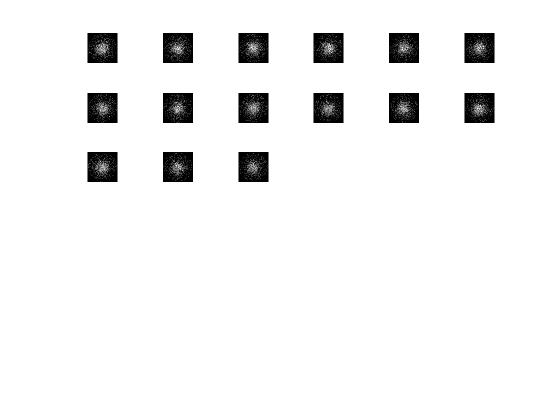

% Load data
data = cell(size(filenames));
atomno = zeros(size(data));
for i = 1:length(data)
    data{i} = imagedata(filenames{i},'crop',{'ellipse',120,276,60,60},'bg',{'avg',15},'plot',{0});
    atomno(i) = sum(sum(getfield(data{i},'od2')));
end

%% Visualize data
figure;
for i = 1:min(6^2,length(filenames))
    subplot(6,6,i);
    imshow(getfield(data{i},'od2'),[0 1.5]); set(gca,'YDir','normal');
end


clearvars i ans

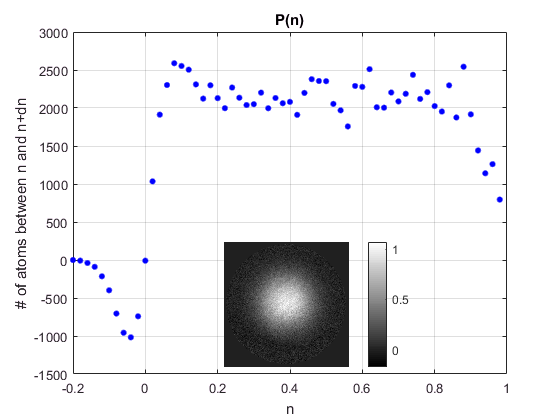

%% P(n) of average
binning_factor = 1;
% average_od = getfield(data{1},'od2');
average_od = imresize(getfield(data{1},'od2'),1/binning_factor,'Method','Box');
% for i = 2:length(data), average_od = average_od + getfield(data{i},'od2'); end
for i = 2:length(data), average_od = average_od + imresize(getfield(data{i},'od2'),1/binning_factor,'Method','Box'); end
average_od = average_od / length(data);
dn_i = 0.02;
n_i_edges = (-0.2:dn_i:1)' - dn_i/2;
[n_i,P_n] = extract_Pn(average_od,'plot',1,'plot_nxy_pos',[0.4 0.1 0.35 0.35],'n_i',n_i_edges);

clearvars i dn_i

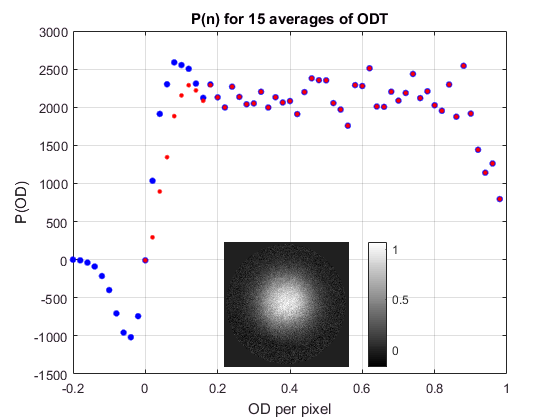

% Folding
ind = find(n_i > -1e-15,1);
P_n_bg = P_n; P_n_bg(ind+1:2*ind-1) = P_n(ind+1:2*ind-1) + flipud(P_n(1:ind-1));
figure;
plot(n_i,P_n,'b.','MarkerSize',15); hold on;
plot(n_i(ind:end),P_n_bg(ind:end),'r.','MarkerSize',10); 
grid on; title('P(n) for 15 averages of ODT'); xlabel('OD per pixel'); ylabel('P(OD)');  hold off; %  legend({'P(n)','flipped'});
axes('Position',[0.4 0.1 0.35 0.35]); imagesc(average_od); axis off; axis image; colormap gray; colorbar; 

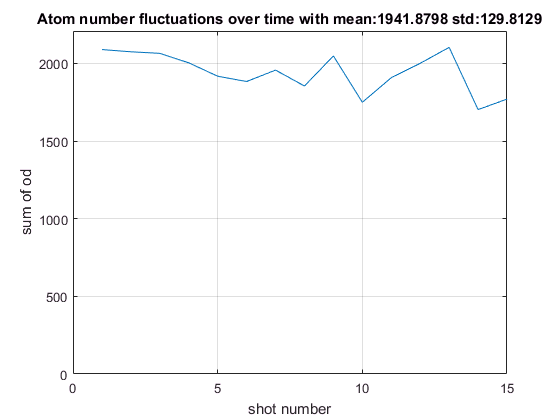

%% Atom number fluctuations
figure; plot(atomno); ylim([0,1.05*max(atomno)]);
grid on; xlabel('shot number'); ylabel('sum of od'); title(['Atom number fluctuations over time with mean:',num2str(mean(atomno)),' std:',num2str(std(atomno))]);

%% 90% atoms within 5% of peak density
% P_n_norm = P_n / sum(P_n);
% range = 10;
% [~,index] = max(P_n);
% peak_frac = sum(P_n_norm(index-range:index+range))
% peak_n = n_i(index);
% range_n = n_i(index+range) - n_i(index)
% (range_n)/peak_n*100

P_n_norm = P_n / sum(P_n);
% P_n_norm = P_n / sum(P_n( find(n_i>0.25,1) :end));
[peak_P,index] = max(P_n_norm);
expect_n = sum(n_i.*P_n_norm);
% peak_n = n_i(index);
peak_n = expect_n

peak_n = 0.5065

percent = 0.1;
index_min = find(n_i >= peak_n * (1-percent),1);
index_max = find(n_i > peak_n * (1+percent),1); 
peak_atoms = sum(P_n_norm(index_min:index_max))*100;
disp([num2str(peak_atoms),'% of atoms are within +- ',num2str(percent*100),'% of peak density']);

13.2517% of atoms are within +- 10% of peak density


%% Plots
% figure;
% plot(n_i2,P_n2,'b-','MarkerSize',10); hold on;
% plot(n_i5,P_n5,'r-','MarkerSize',10);
% % plot(n_i10,P_n10,'k--','MarkerSize',10);
% plot(n_i18,P_n18,'k-','MarkerSize',10);
% legend({'2 images','5 images','18 images'});
% grid on; title('P(n) full box with small aperture'); xlabel('OD per pixel'); ylabel('P(OD)'); hold off; 


% Figure FFT vs Binning
% figure;
% plot(n_i_bin1,P_n_bin1,'r-'); hold on;
% plot(n_i_bin2,4*P_n_bin2,'b-');
% plot(n_i_fft,P_n_fft,'k-');
% plot(n_i_bin4,16*P_n_bin4,'c-');
% plot(n_i_bin8,8*8*P_n_bin8,'m-');
% hold off;
% xlim([0 1]); xlabel(['OD']);
% ylim([0 6e4]); ylabel('P(OD)');
% legend({'Raw Image','Binned 2by2','Low pass box filter','Binned 4by4','Binned 8by8'},'Location','Northwest'); 
% grid on;
% title('Comparing different binning');